% Problem 1.1

clc; clear; close all;

disp('Problem 1.1')

Problem 1.1



% Given covariance matrix
cov = [4, 1, 2;
       1, 9, -3;
       2, -3, 25]

cov =      4     1     2
     1     9    -3
     2    -3    25


% Using eig
disp('Problem 1.1.1')

Problem 1.1.1


[eig_vec_, eig_val_] = eig(cov)

eig_vec_ =     0.9624    0.2586    0.0826
   -0.2419    0.9550   -0.1715
   -0.1232    0.1451    0.9817


eig_val_ =     3.4926         0         0
         0    8.8151         0
         0         0   25.6923



% Confirm that cov*eig_vec = eig_vec*eig_val
cov*eig_vec_ - eig_vec_*eig_val_

ans = 1.0e-14 *

   -0.0444         0    0.1332
    0.1554   -0.1776   -0.0888
   -0.0278   -0.0222         0



% Doing it manually
syms l
I = eye(size(cov))

I =      1     0     0
     0     1     0
     0     0     1


char_eq = det(cov - l * I)

$$char\_eq = -l^{3}+38\,l^{2}-347\,l+791$$

% Eigen values
eig_val = diag(double(solve(char_eq, l)))

eig_val =     3.4926         0         0
         0    8.8151         0
         0         0   25.6923



% Eigen vectors
cov_lambda1 = cov - eig_val(1,1) * I;
eig_vec_1 = null(cov_lambda1);
eig_vec_1 = eig_vec_1 / norm(eig_vec_1);

cov_lambda2 = cov - eig_val(2,2) * I;
eig_vec_2 = null(cov_lambda2);
eig_vec_2 = eig_vec_2 / norm(eig_vec_2);

cov_lambda3 = cov - eig_val(3,3) * I;
eig_vec_3 = null(cov_lambda3);
eig_vec_3 = eig_vec_3 / norm(eig_vec_3);

eig_vec = [eig_vec_1, eig_vec_2, eig_vec_3]

eig_vec =    -0.9624    0.2586    0.0826
    0.2419    0.9550   -0.1715
    0.1232    0.1451    0.9817


disp('Problem 1.1.2')

Problem 1.1.2


% Verify that |Sigma| = Pi^3_i=1 (lambda_i)
eig_val_prod = prod(eig_val);
eig_val_prod_ = prod(eig_val_);
det(cov);

det(cov) - eig_val_prod

ans =    791   791   791


det(cov) - eig_val_prod_

ans =    791   791   791



% False?

disp('Problem 1.1.3')

Problem 1.1.3


% Verify that trace(cov) = Pi^3_i=1 (lambda_i)
trace(cov) - eig_val_prod

ans =     38    38    38


trace(cov) - eig_val_prod_

ans =     38    38    38



% Use EVD and square root to find cov^(1/2) and cov^(-1/2)
D_sqrt = diag(sqrt(eig_val));
D_inv_sqrt = diag(1 ./ sqrt(eig_val));

% Compute cov^(1/2)
cov_sqrt = eig_vec .* D_sqrt .* eig_vec'

cov_sqrt =     1.7311    0.1169    0.0190
    0.1857    2.7080   -0.0739
    0.0516   -0.1261    4.8851



% Compute cov^(-1/2)
cov_inv_sqrt = eig_vec .* D_inv_sqrt .* eig_vec'

cov_inv_sqrt =     0.4957    0.0335    0.0054
    0.0211    0.3072   -0.0084
    0.0020   -0.0049    0.1901


% Problem 1.2

clc; clear; close all;

disp('Problem 1.2')

Problem 1.2



% Loading data which contains track records for women in 54 countries for
% the running disciplines 100m [s], 200m [s], 400m [s], 800m [min], 1500m
% [min], 3000m [min], marathon [min].
 
data = load("dataset_problem_1_2.dat")

data =    11.5700   22.9400   52.5000    2.0500    4.2500    9.1900  150.3200
   11.1200   22.2300   48.6300    1.9800    4.0200    8.6300  143.5100
   11.1500   22.7000   50.6200    1.9400    4.0500    8.7800  154.3500
   11.1400   22.4800   51.4500    1.9700    4.0800    8.8200  143.0500
   11.4600   23.0500   53.3000    2.0700    4.2900    9.8100  174.1800
   11.1700   22.6000   50.6200    1.9700    4.1700    9.0400  147.4100
   10.9800   22.6200   49.9100    1.9700    4.0000    8.5400  148.3600
   11.6500   23.8400   53.6800    2.0000    4.2200    9.2600  152.2300
   10.7900   22.0100   49.8100    1.9300    3.8400    8.1000  139.3900
   11.3100   22.9200   49.6400    2.0400    4.3400    9.3700  155.1900



% I'm gonna convert the second columns into minutes, for the graphs.
data(:, 1:3) = data(:, 1:3) / 60;

% Original headers and data
headers = {'100m [min]', '200m [min]', '400m [min]', '800m [min]', '1500m [min]', '3000m [min]', 'marathon [min]'};
data = array2table(data, 'VariableNames', headers)

data = 54×7 table
    100m [min]    200m [min]    400m [min]    800m [min]    1500m [min]    3000m [min]    marathon [min]
    __________    __________    __________    __________    ___________    ___________    ______________

     0.19283       0.38233         0.875         2.05          4.25           9.19            150.32    
     0.18533        0.3705        0.8105         1.98          4.02           8.63            143.51    
     0.18583       0.37833       0.84367         1.94          4.05           8.78            154.35    
     0.18567       0.37467        0.8575         1.97          4.08           8.82            143.05    
       0.191       0.38417       0.88833         2.07          4.29           9.81            174.18    
     0.1

disp('Problem 1.2.1')

Problem 1.2.1


% Calculate descriptive statistics
descriptive_statistics = [mean(table2array(data));
                          std(table2array(data));
                          range(table2array(data))];

% Define row names for descriptive statistics
rows = {'Mean', 'STD', 'Range'};

% Create a table for descriptive statistics with the same column headers
descriptive_statistics = array2table(descriptive_statistics, 'RowNames', rows, 'VariableNames', headers)

descriptive_statistics = 3×7 table
             100m [min]    200m [min]    400m [min]    800m [min]    1500m [min]    3000m [min]    marathon [min]
             __________    __________    __________    __________    ___________    ___________    ______________

    Mean        0.1893       0.38531       0.86648        2.0224        4.1894         9.0807          153.62    
    STD      0.0065684      0.015484      0.043287      0.086873       0.27237        0.81533           16.44    
    Range     0.033833      0.076167       0.23417           0.4          1.58           5.02           85.89    


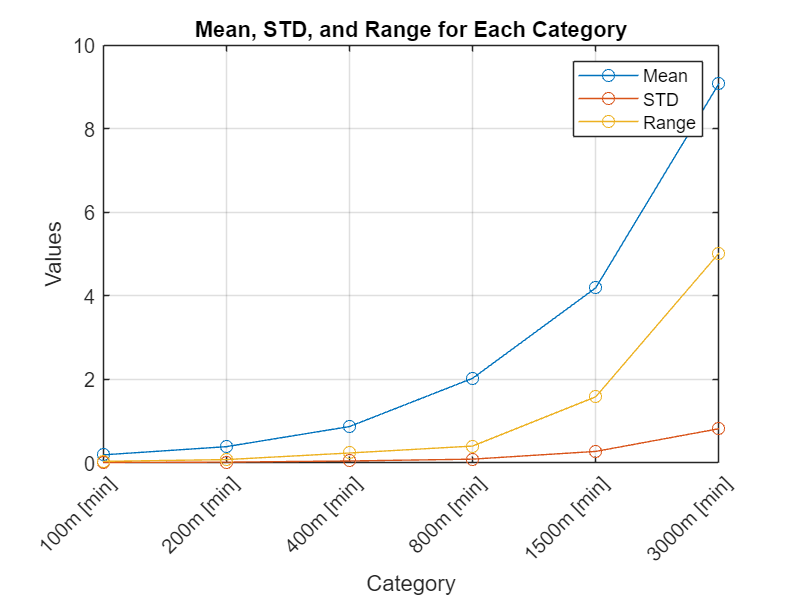


% Create a line plot excluding marathon, so the plot looks better.
figure;
% Transpose and plot with markers
plot(table2array(descriptive_statistics(:, 1:end-1))', 'o-');

% Add x-axis labels and title
xlabel('Category');
ylabel('Values');
title('Mean, STD, and Range for Each Category');

% Add x-axis labels
set(gca, 'XTick', 1:numel(headers), 'XTickLabel', headers);

% Add legend for Mean, STD, and Range
legend('Mean', 'STD', 'Range');

% Rotate x-axis labels for better readability (optional)
xtickangle(45);

% Display the plot
grid on;


% The descriptive statistics seem to increase proportionally with distance.

disp('Problem 1.2.2')

Problem 1.2.2


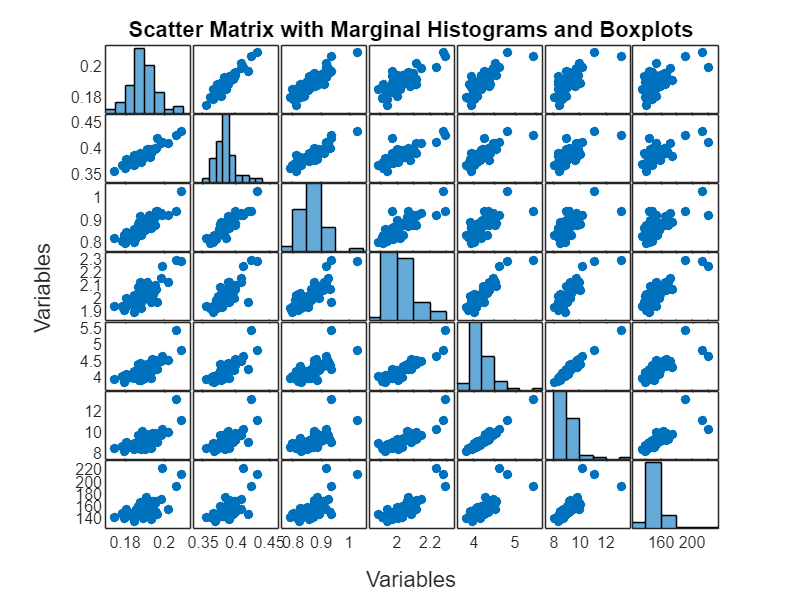

% Make plots of the multivariate scatter matrix plus marginal histograms and boxplots
% Create a scatter matrix with marginal histograms and boxplots
figure;
plotmatrix(table2array(data));
xlabel('Variables');
ylabel('Variables');
title('Scatter Matrix with Marginal Histograms and Boxplots');


% It seems to me that this shows the descriptive statistics to be
% proportional to distance.